clear; clc; close all;

1

% initialize question
global lambda;
global ro;
global c;
lambda = 48;
ro = 7800;
c = 452;

timInt_m = 1; % einschritt theta
theta = 0.5;
timestep = 500;
t_star = 5000;

r = 0.02;
b = 0.3;
h = 0.3;
T0 = zeros(18,1)+300;
T1 = 600;
T2 = 300;

nodes = gen_nodes(r,b,h);
elements = [1 2 6 5
    2 3 7 6
    3 4 8 7
    5 6 10 9
    6 7 11 10
    7 12 14 11
    7 8 13 12
    9 10 16 15
    10 11 17 16
    11 14 18 17
    ];
dbc = [1 T1
    2 T1
    3 T1
    4 T1
    12 T2
    13 T2
    14 T2
    18 T2
    ];


T = solve_question(nodes,elements,dbc,0,timestep,t_star,T0,timInt_m,theta);
sol = T(:,end);
% display solution
display(sol(15));

  483.0905



display(sol(16));

  463.9204



display(sol(17));

  441.2822



display(sol(18));

   300



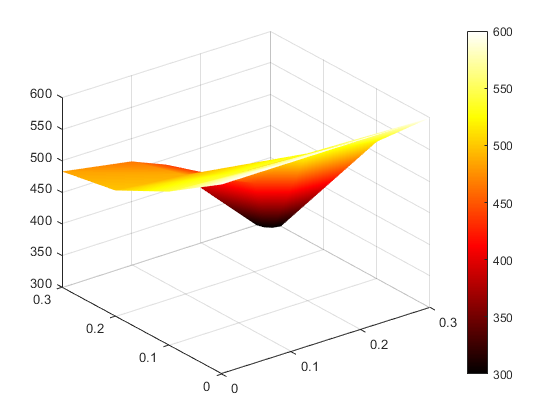

figure;
quadplot(nodes,elements,sol);
shading interp;
colormap hot;
colorbar;

   5.4108e+12



  -6.9345e+12



   8.1834e+12



   300



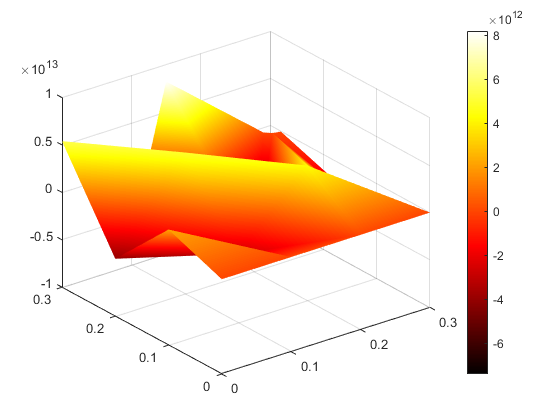

  496.8121



  495.7867



  490.9753



   300



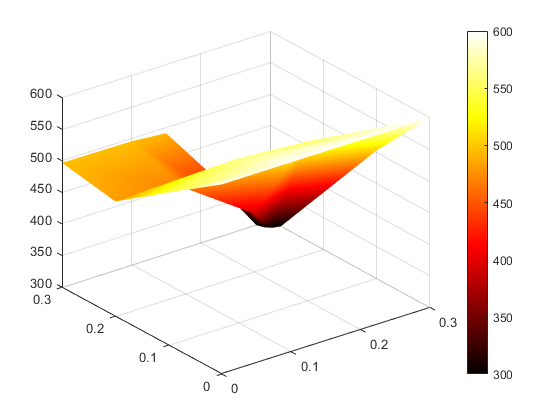

  482.7369



  463.5486



  440.7880



   300



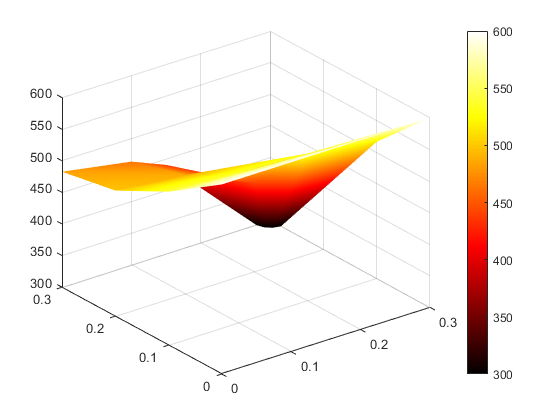

for timInt_m=2:4
    T = solve_question(nodes,elements,dbc,0,timestep,t_star,T0,timInt_m,theta);
    sol = T(:,end);
    % display solution
    display(sol(15));
    display(sol(16));
    display(sol(17));
    display(sol(18));
    figure;
    quadplot(nodes,elements,sol);
    shading interp;
    colormap hot;
    colorbar;
end

for ts = 1:size(T,2)
    sol = T(:,ts);
    if any(sol(nodes(:,2)==h)>450)
        break;
    end
end

% display solution
display(sol(15));

  462.6345



display(sol(16));

  446.0152



display(sol(17));

  426.7693



display(sol(18));

   300



display(timestep*(ts-1));

        3500



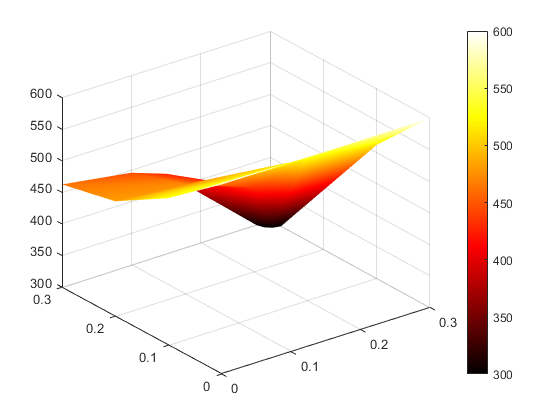

figure;
quadplot(nodes,elements,sol);
shading interp;
colormap hot;
colorbar;

function nodes = gen_nodes(r,b,h)
    nodes = zeros(18,2);
    [x, y] = meshgrid(linspace(0,b,4),linspace(0,h,4));
    nodes([1:11,15:16],:) = [y([1:11,13:14])',x([1:11,13:14])'];
    nodes(12,:)=[b-r*sin(pi/6),b-r*cos(pi/6)];
    nodes(13,:)=[b,h-r];
    nodes(14,:)=[b-r*cos(pi/6),b-r*sin(pi/6)];
    nodes(17,:)=[b/2,h];
    nodes(18,:)=[b-r,h];
end

function T = solve_question(nodes,elements,dbc,start_t,timestep,end_t,T0,timInt_m,theta)
    n = 2;
    t=start_t:timestep:end_t;
    T = zeros(size(nodes,1),numel(t));
    T(:,1) = T0;
    osol = T0;
    sol = T0;
    gpx = gx2dref(n);
    gpw = gw2dref(n);
    for ts=2:numel(t)
        sysmat = zeros(size(nodes,1));
        rhs = zeros(size(nodes,1),1);
        for e=1:size(elements,1)
            ele = elements(e,:);
            elenodes = nodes(ele,:);
            elesol = sol(ele);
            eleosol = osol(ele);
            [elemat,elevec] = evaluate_instat(elenodes,gpx,gpw,elesol,eleosol,timInt_m,timestep,theta,ts==2);
            [sysmat,rhs] = assemble(elemat,elevec,sysmat,rhs,ele);
        end
        [sysmat,rhs] = assignDBC(sysmat,rhs,dbc);
        osol = sol;
        sol = sysmat\rhs;
        T(:,ts) = sol;
    end
end

